# Bifurcation diagram for the star graph

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

Note how each of the routines outputs one or more identifiers that are used to call later routines that continue from points on the computed branches

## Construct the quantum graph and find the first few eigenfunctions

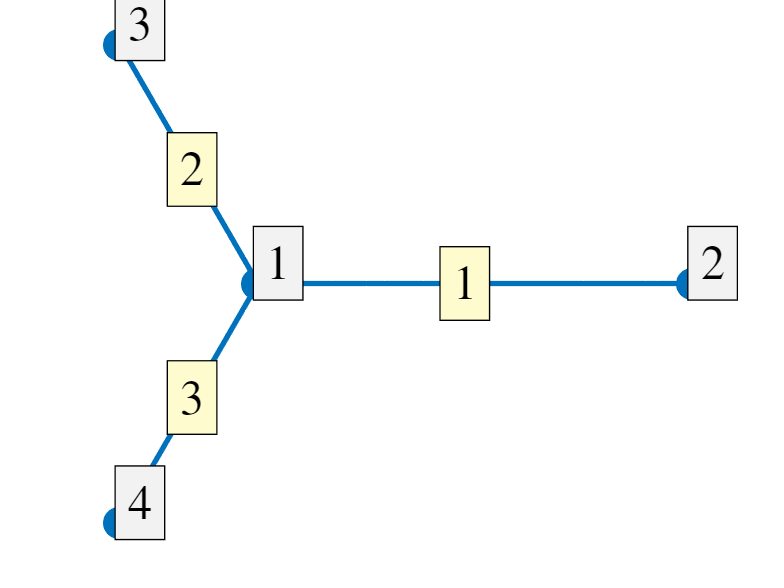

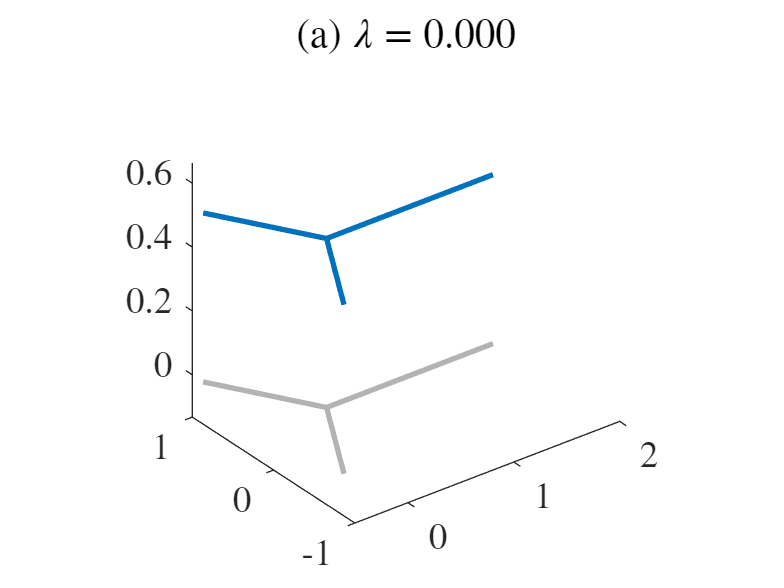

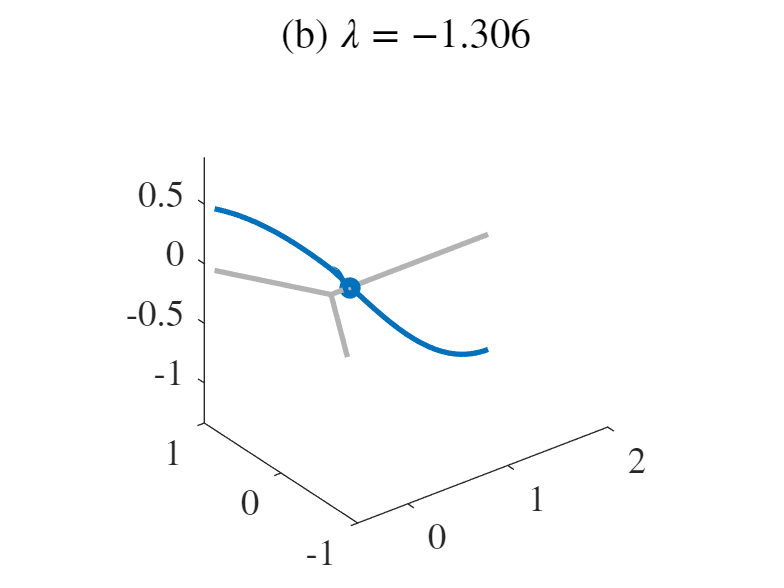

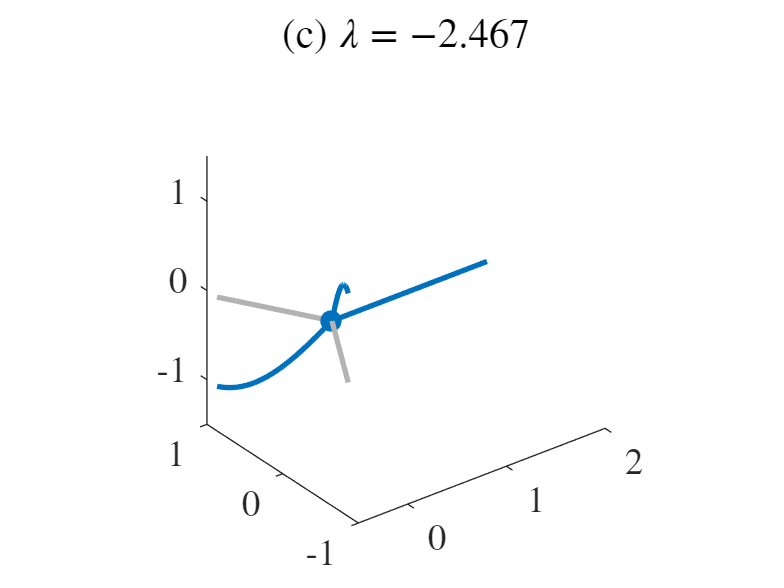

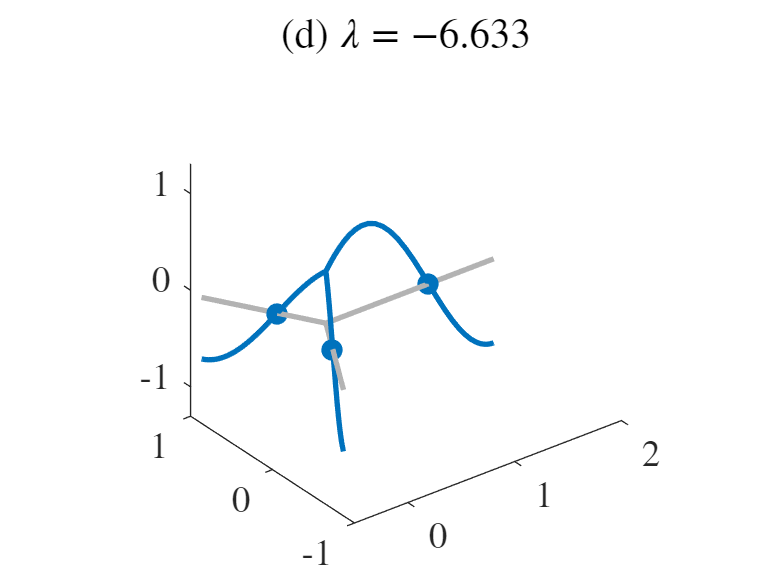

Saved to directory data\star\003.
Run number is 3.


tag='star';
Phi = quantumGraphFromTemplate(tag,'LVec',[pi/2 1 1],'discretization','Chebyshev','nx',32,'n',3);

nToPlot=4;
nDoubles=2;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-2,'NThresh',4,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

Lambda threshold crossed.
Branch number 1.
Data saved to directory data\star\003\branch001.
Branching Bifurcation at solution number 12.
Branching Bifurcation at solution number 16.


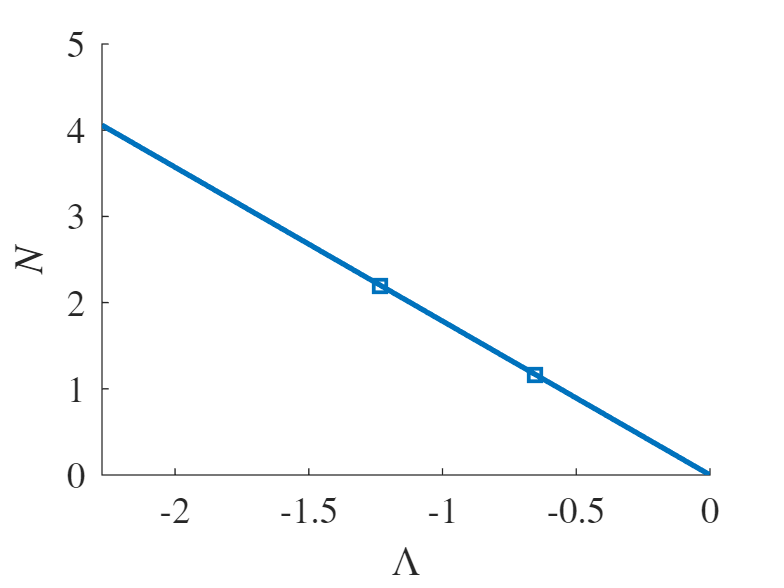

bifurcationDiagram(tag,diagramNumber)

## Compute some branches that bifurcate from this first branch

[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\star\003\branch002.
No branching bifurcations found.


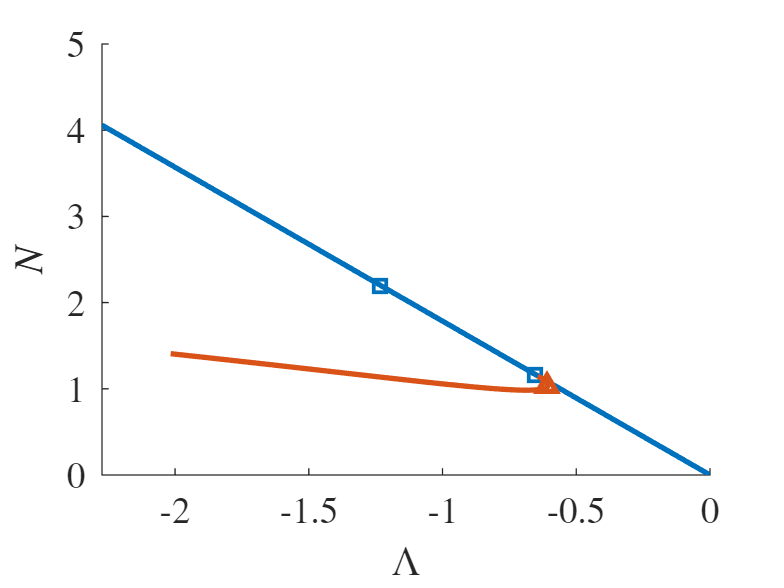

bifurcationDiagram(tag,diagramNumber)

[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),-1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data\star\003\branch003.
Branching Bifurcation at solution number 8.


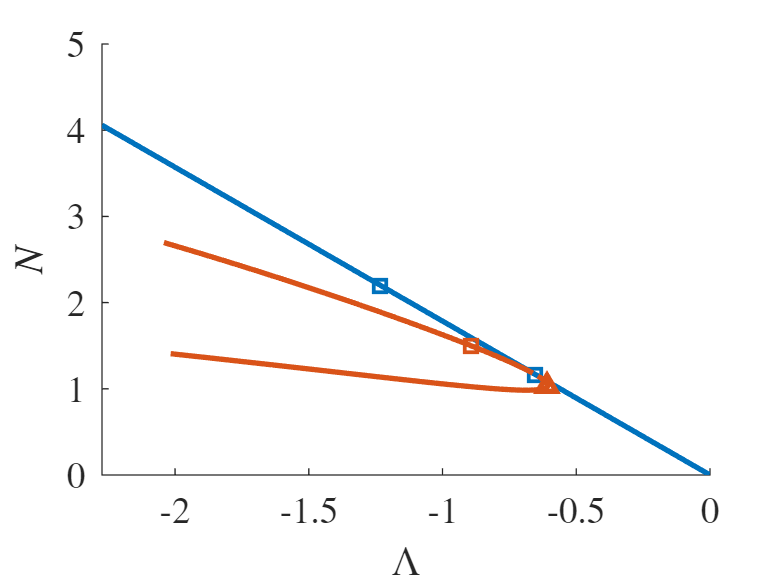

bifurcationDiagram(tag,diagramNumber)

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data\star\003\branch004.
No branching bifurcations found.


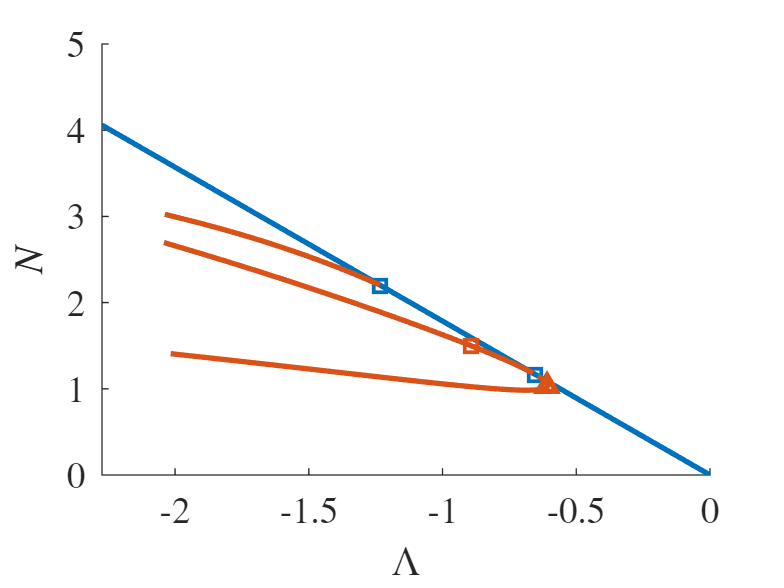

bifurcationDiagram(tag,diagramNumber)

[bn5,bl5]=continueFromBranchPoint(tag,diagramNumber,bn3,bl3(1),1,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data\star\003\branch005.
No branching bifurcations found.


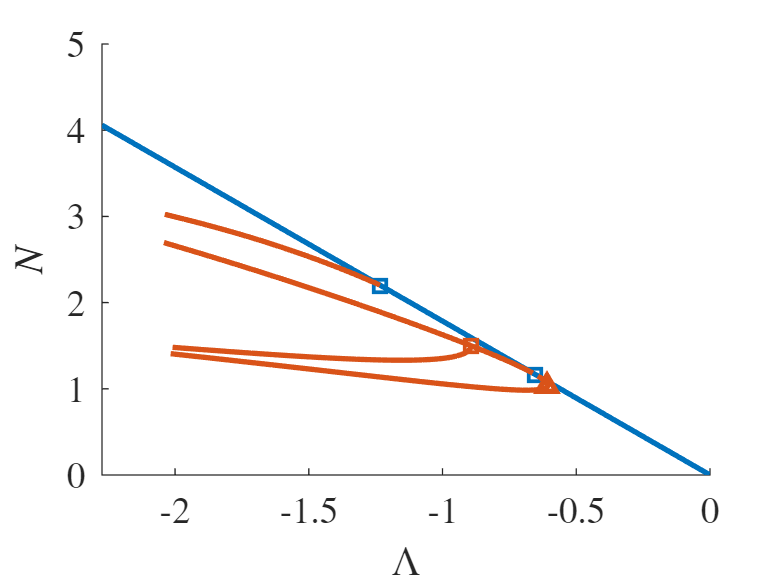

bifurcationDiagram(tag,diagramNumber)

## Plot some solutions

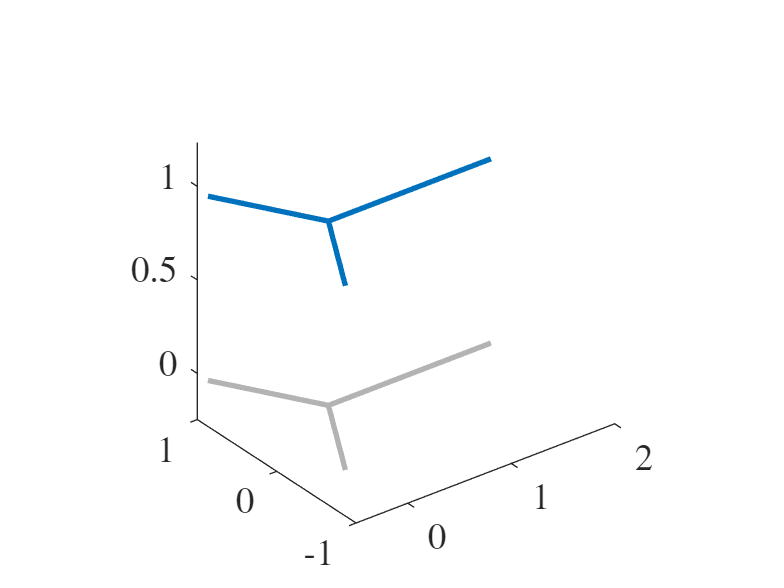

plotSolution(tag,diagramNumber,bn1,19)

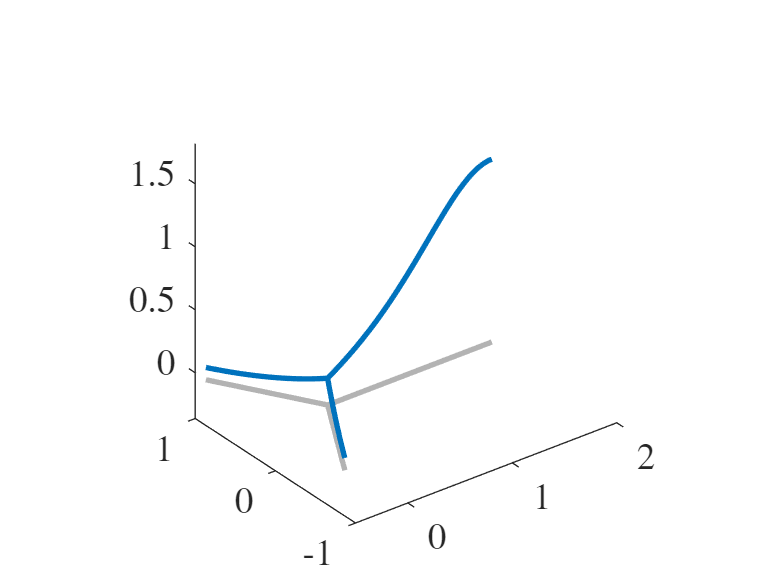

plotSolution(tag,diagramNumber,bn2,'last')

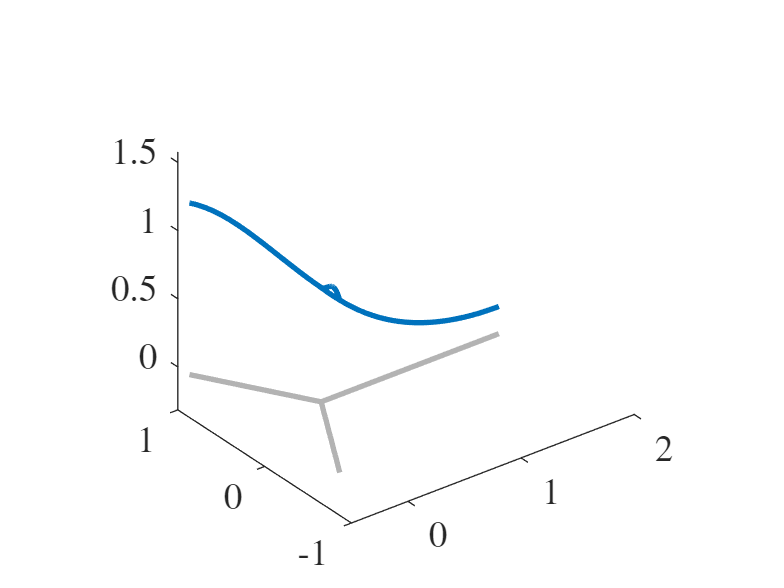

plotSolution(tag,diagramNumber,bn3,'last')

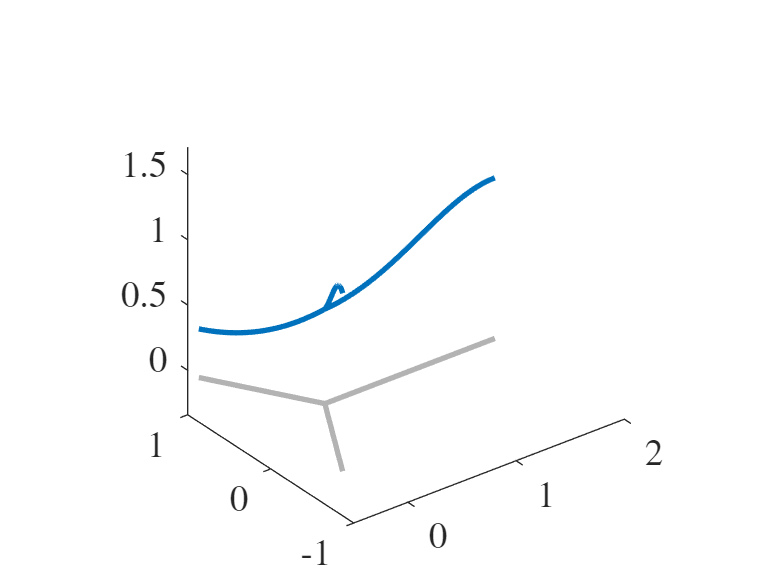

plotSolution(tag,diagramNumber,bn4,'last')

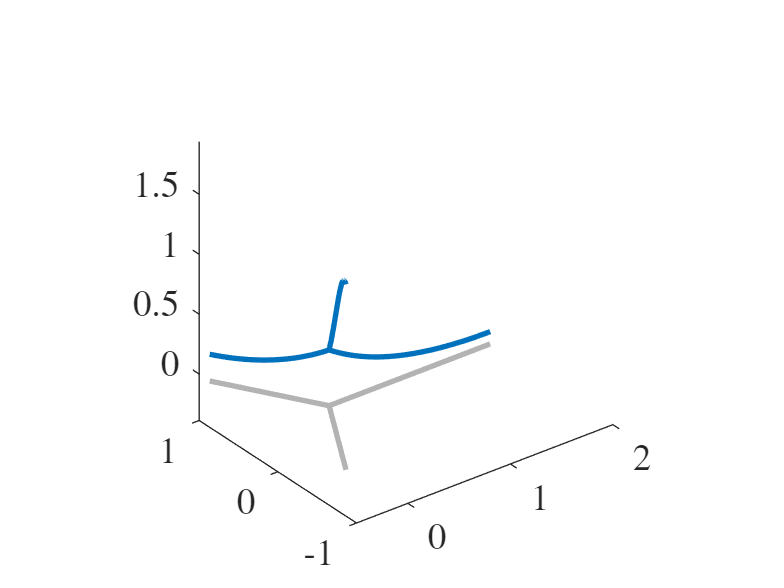

plotSolution(tag,diagramNumber,bn5,'last')